绘制累计平均收益率曲线（将第-10天的净值设为1）average return

i=1;
average_Rit=[];
while i<=21
    average_Rit=[average_Rit 1+sum(Rit(:,i))/8158];
    i=i+1;
end
average_Rit

average_Rit =     0.9995    0.9995    1.0011    0.9999    1.0001    1.0014    1.0019    1.0011    1.0014    0.9996    0.9976    0.9992    1.0014    1.0006    1.0000    0.9998    1.0009    1.0006    0.9995    1.0008    1.0004


%计算每一天的净值
i=1;
Daily_net_value=1*cumprod(average_Rit)

Daily_net_value =     0.9995    0.9990    1.0001    1.0000    1.0001    1.0016    1.0035    1.0046    1.0061    1.0057    1.0032    1.0025    1.0039    1.0045    1.0045    1.0043    1.0052    1.0058    1.0053    1.0062    1.0065


x=-10:10

x =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


y=Daily_net_value

y =     0.9995    0.9990    1.0001    1.0000    1.0001    1.0016    1.0035    1.0046    1.0061    1.0057    1.0032    1.0025    1.0039    1.0045    1.0045    1.0043    1.0052    1.0058    1.0053    1.0062    1.0065


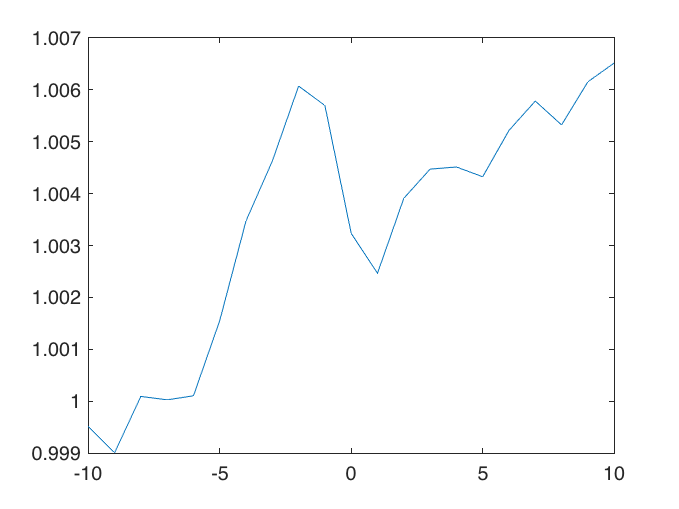

plot(x,y)